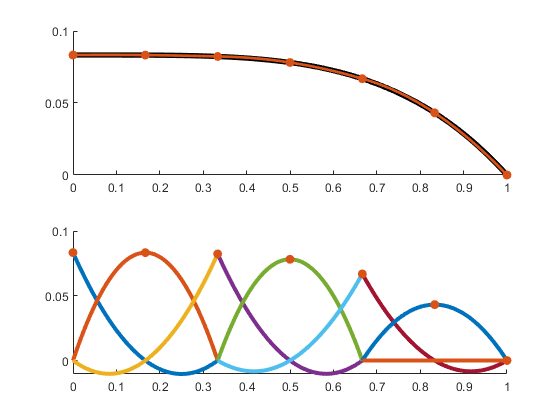

clear

x = sym('x','real');
f = x^2;
g = sym(0);
h = sym(0);
exactSolution = computeExactSolution(f,g,h);

f = symfun(f,symvar(f));
eDegree = 2;
nELEM = 3;
feSolution = main(nELEM,eDegree,f,g,h);

figure
subplot(2,1,1)
hold on
ax = gca;
pExact = fplot(exactSolution.U,exactSolution.domain,'k','LineWidth',4);
pApprx = fplot(feSolution.U,exactSolution.domain,'LineWidth',2);
scatter(feSolution.Mesh.Nodes, feSolution.LinearSystem.d,'Marker','o','MarkerFaceColor',pApprx.Color,'MarkerEdgeColor',pApprx.Color);

subplot(2,1,2)
hold on
for e = 1:nELEM

    scaledBasisFuns = feSolution.Elements(e).GDOF .* feSolution.Elements(e).GBasisFuns;
    pBfun = fplot(scaledBasisFuns, feSolution.Elements(e).GDomain,'LineWidth',3);
end
scatter(feSolution.Mesh.Nodes, feSolution.LinearSystem.d,'Marker','o','MarkerFaceColor',pApprx.Color,'MarkerEdgeColor',pApprx.Color);